## Sentiment Analysis for YouTube

The following is a modified verison of the Train Sentiment Classifer MathWorks example. It has been modified to generate two scores for one for the negativity of the commetns and one for the positivity. 

## Call the sentiment functions

This section calls the functions at the end of this file for text analysis. 

**Note: **This file must be in the same directory as a the lexicons for this to work. 

rng('default')
emb = fastTextWordEmbedding;
data = readLexicon;

## Prepare Data for Training

To train the sentiment classifier, convert the words to word vectors using the pretrained word embedding `emb`. First remove the words that do not appear in the word embedding `emb`.

idx = ~isVocabularyWord(emb,data.Word);
data(idx,:) = [];

Set aside 10% of the words at random for testing.

numWords = size(data,1);
cvp = cvpartition(numWords,'HoldOut',0.1);
dataTrain = data(training(cvp),:);
commentData = data(test(cvp),:);

Convert the words in the training data to word vectors using `word2vec`.

wordsTrain = dataTrain.Word;
XTrain = word2vec(emb,wordsTrain);
YTrain = dataTrain.Label;

## Train Sentiment Classifier

Train a support vector machine (SVM) classifier which classifies word vectors into positive and negative categories.

mdl = fitcsvm(XTrain,YTrain);

## Test Classifier

Convert the words in the test data to word vectors using `word2vec`.

wordsTest = commentData.Word;
XTest = word2vec(emb,wordsTest);
YTest = commentData.Label;

Predict the sentiment labels of the test word vectors.

[YPred,scores] = predict(mdl,XTest);

Visualize the classification accuracy in a confusion matrix.

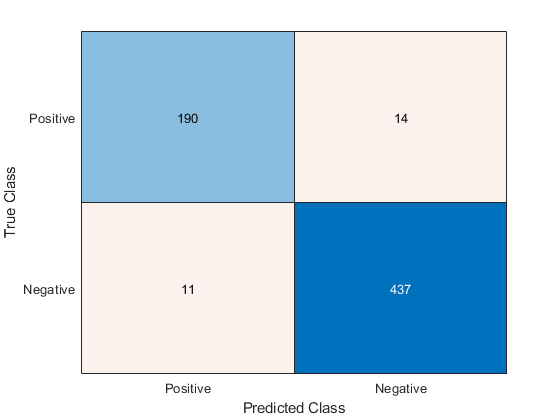

figure;
confusionchart(YTest,YPred);

## Pulling YouTube Comments

Insert Urls programatically from a spreadsheet

## Setup the Import Options

Setup how you import the spreadsheet of youtube urls here. 

opts = spreadsheetImportOptions("NumVariables", 1);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "YOUR CELL RANGE HERE";

% Specify column names and types
opts.VariableNames = "Var1";
opts.SelectedVariableNames = "Var1";
opts.VariableTypes = "string";
opts = setvaropts(opts, 1, "WhitespaceRule", "preserve");
opts = setvaropts(opts, 1, "EmptyFieldRule", "auto");

% Import the data
videoList = readtable("YOUR FILE LOCATION HERE", opts, "UseExcel", false)

videoList = 11×1 table
                        Var1                     
    _____________________________________________

    "https://www.youtube.com/watch?v=D_hmws6dwgg"
    "https://www.youtube.com/watch?v=DPLBPdux6bs"
    "https://www.youtube.com/watch?v=2Z4959acjKs"
    "https://www.youtube.com/watch?v=1-jURfDzP1s"
    "https://youtu.be/s1McIoTovsk"               
    "https://youtu.be/mwn8xhgNpFY"               
    "https://www.youtube.com/watch?v=B-SAMofba-o"
    "https://youtu.be/wkfEZmsQqiA"               
    "https://youtu.be/me53aM6n_1Y"               
    "https://www.youtube.com/watch?v=iOmqgewj5XI"
    "https://www.youtube.com/watch?v=mDAvo6bDp4s"


## Convert to output type

videoListCell = table2cell(videoList);
numIdx = cellfun(@(x) ~isnan(str2double(x)), videoListCell);
videoListCell(numIdx) = cellfun(@(x) {str2double(x)}, videoListCell(numIdx))

videoListCell = 11×1 cell array
    {["https://www.youtube.com/watch?v=D_hmws6dwgg"]}
    {["https://www.youtube.com/watch?v=DPLBPdux6bs"]}
    {["https://www.youtube.com/watch?v=2Z4959acjKs"]}
    {["https://www.youtube.com/watch?v=1-jURfDzP1s"]}
    {["https://youtu.be/s1McIoTovsk"               ]}
    {["https://youtu.be/mwn8xhgNpFY"               ]}
    {["https://www.youtube.com/watch?v=B-SAMofba-o"]}
    {["https://youtu.be/wkfEZmsQqiA"               ]}
    {["https://youtu.be/me53aM6n_1Y"               ]}
    {["https://www.youtube.com/watch?v=iOmqgewj5XI"]}
    {["https://www.youtube.com/watch?v=mDAvo6bDp4s"]}


## Clear temporary variables

clear opts

## Pull YouTube Video IDs

Takes the urls and extracts the Video IDs for the comment scraper

videoIDList = string(zeros(length(videoListCell), 1)')

videoIDList = 1×11 string array
    "0"    "0"    "0"    "0"    "0"    "0"    "0"    "0"    "0"    "0"    "0"


for i = 1:length(videoListCell)
    videoUrl = char(string(videoListCell(i)));
    if videoUrl(9) == 'w'
        videoID = videoUrl(33:43);
    elseif videoUrl(9) == 'y'
        videoID = videoUrl(18:28);
    else
        videoID = 'NaN';
    end
    videoIDList(i) = string(videoID);
end

## Loop through all the comments

Begining of the loop. Each time the loop iterates, the comments from the individual video are scrapped. 

for i = 1:length(videoIDList)
py.downloader.main(videoIDList(i),"outjsonFile2.json",inf);
%% Read json file and rearrange
x = importdata('outjsonFile2.json');
% Best way to import json like this? (also tried fileread, textscan w/ similar 
% results but this is friendliest to converting, though they all return cells)
x = string(x);
% This should be better for arrays?? Too many conversions required for 
% a common arrangement

Downloaded 1 comment(s)
Downloaded 2 comment(s)
Downloaded 3 comment(s)
Downloaded 4 comment(s)
Downloaded 5 comment(s)
Downloaded 6 comment(s)
Downloaded 7 comment(s)
Downloaded 8 comment(s)
Downloaded 9 comment(s)
Downloaded 10 comment(s)
Downloaded 11 comment(s)
Downloaded 12 comment(s)
Downloaded 13 comment(s)
Downloaded 14 comment(s)
Downloaded 15 comment(s)
Downloaded 16 comment(s)
Downloaded 17 comment(s)
Downloaded 18 comment(s)
Downloaded 19 comment(s)
Downloaded 20 comment(s)
Downloaded 21 comment(s)
Downloaded 22 comment(s)
Downloaded 23 comment(s)
Downloaded 24 comment(s)
Downloaded 25 comment(s)
Downloaded 26 comment(s)
Downloaded 27 comment(s)
Downloaded 28 comment(s)
Downloaded 29 comment(s)
Downloaded 30 comment(s)
Downloaded 31 comment(s)
Downloaded 32 comment(s)
Downloaded 33 comment(s)
Downloaded 34 comment(s)
Downloaded 35 comment(s)
Downloaded 36 comment(s)
Downloaded 37 comment(s)
Downloaded 38 comment(s)
Downloa

Downloaded 1 comment(s)
Downloaded 2 comment(s)
Downloaded 3 comment(s)
Downloaded 4 comment(s)
Downloaded 5 comment(s)
Downloaded 6 comment(s)
Downloaded 7 comment(s)
Downloaded 8 comment(s)
Downloaded 9 comment(s)
Downloaded 10 comment(s)
Downloaded 11 comment(s)
Downloaded 12 comment(s)
Downloaded 13 comment(s)
Downloaded 14 comment(s)
Downloaded 15 comment(s)
Downloaded 16 comment(s)
Downloaded 17 comment(s)
Downloaded 18 comment(s)
Downloaded 19 comment(s)
Downloaded 20 comment(s)
Downloaded 21 comment(s)
Downloaded 22 comment(s)
Downloaded 23 comment(s)
Downloaded 24 comment(s)
Downloaded 25 comment(s)
Downloaded 26 comment(s)
Downloaded 27 comment(s)
Downloaded 28 comment(s)
Downloaded 29 comment(s)
Downloaded 30 comment(s)
Downloaded 31 comment(s)
Downloaded 32 comment(s)
Downloaded 33 comment(s)
Downloaded 34 comment(s)
Downloaded 35 comment(s)
Downloaded 36 comment(s)
Downloaded 37 comment(s)
Downloaded 38 comment(s)
Downloa

clear comments
comments = table;
for ii = 1:length(x)
    y1 = jsondecode(x(ii));
    y2 = struct2table(y1,'AsArray',true);
    y2 = convertvars(y2,1:4,'string');  % there are errors when concatenating if not converted to string
    comments = [comments;y2];
end

This takes the JSON file that the scrapper outputs and converts it to a cell array for the next section. 

% commentFile = "commentFile.JSON"
% val = jsondecode(fileread(commentFile))
% commentData = string(struct2cell(val))

## Calculate Sentiment of Collections of Text

To calculate the sentiment of a piece of text, for example a review, predict the sentiment score of each word in the text and take the mean sentiment score.

Create a function which tokenizes and preprocesses the text data so it can be used for analysis. The function `preprocessText`, listed at the end of the example, performs the following steps in order:

- Tokenize the text using `tokenizedDocument`.

- Erase punctuation using `erasePunctuation`.

- Remove stop words (such as "and", "of", and "the") using `removeStopWords`.

- Convert to lowercase using `lower`.

Use the preprocessing function `preprocessText` to prepare the text data. This step can take a few minutes to run.

if isempty(comments)
    aveNegative = "NaN"
    avePositive = "NaN"
    sumNegative = "NaN"
    sumPositive = "NaN"
    tempScoreTable = table(videoListCell(i), aveNegative, avePositive, sumNegative, sumPositive)
else
    newComments = table2array(comments);
    newComments = newComments(:, 2);
    documents = preprocessText(newComments);

aveNegative = "NaN"

avePositive = "NaN"

sumNegative = "NaN"

sumPositive = "NaN"

tempScoreTable = 1×5 table
                         Var1                          aveNegative    avePositive    sumNegative    sumPositive
    _______________________________________________    ___________    ___________    ___________    ___________

    ["https://www.youtube.com/watch?v=2Z4959acjKs"]       "NaN"          "NaN"          "NaN"          "NaN"   


aveNegative = "NaN"

avePositive = "NaN"

sumNegative = "NaN"

sumPositive = "NaN"

tempScoreTable = 1×5 table
                         Var1                          aveNegative    avePositive    sumNegative    sumPositive
    _______________________________________________    ___________    ___________    ___________    ___________

    ["https://www.youtube.com/watch?v=mDAvo6bDp4s"]       "NaN"          "NaN"          "NaN"          "NaN"   


Remove the words from the documents that do not appear in the word embedding `emb`.

    idx = ~isVocabularyWord(emb,documents.Vocabulary);
    documents = removeWords(documents,idx);

To calculate the sentiment of a given piece of text, compute the sentiment score for each word in the text and calculate the mean sentiment score.

For a selection of the documents, calculate the mean sentiment score. For each document, convert the words to word vectors, predict the sentiment score on the word vectors, transform the scores using the score-to-posterior transform function and then calculate the mean sentiment score.

    clear sentimentScore
    for j = 1:numel(documents)
        words = string(documents(j));
        vec = word2vec(emb,words);
        [~,scores] = predict(mdl,vec);
        sentimentScore(j) = mean(scores(:,1));
    end

View the predicted sentiment scores with the text data. Scores greater than 0 correspond to positive sentiment, scores less than 0 correspond to negative sentiment, and scores close to 0 correspond to neutral sentiment.

    ScoreExample = [sentimentScore' newComments];
    numScore = str2double(ScoreExample(:,1))';
    negativeScores = zeros(1, length(numScore));
    positiveScores = zeros(1, length(numScore));
    negCount = 1;
    posCount = 1;
    for k = 1:length(numScore)
        if numScore(k) < 0
            negativeScores(negCount) = numScore(k);
            negCount = negCount + 1;
        else 
            positiveScores(posCount) = numScore(k);
            posCount = posCount + 1;
        end
    
    end
    negativeScores = rmmissing(negativeScores(1:negCount - 1));
    positiveScores = rmmissing(positiveScores(1:posCount - 1));
    aveNegative = mean(negativeScores);
    sumNegative = sum(negativeScores);
    avePositive = mean(positiveScores);
    sumPositive = sum(positiveScores);

    tempScoreTable = table(videoListCell(i), aveNegative, avePositive, sumNegative, sumPositive);
end
if i == 1
    ScoreTable = tempScoreTable;
else
   ScoreTable = [ScoreTable; tempScoreTable];
end
end

ScoreTable.Var1

ans = 11×1 cell array
    {["https://www.youtube.com/watch?v=D_hmws6dwgg"]}
    {["https://www.youtube.com/watch?v=DPLBPdux6bs"]}
    {["https://www.youtube.com/watch?v=2Z4959acjKs"]}
    {["https://www.youtube.com/watch?v=1-jURfDzP1s"]}
    {["https://youtu.be/s1McIoTovsk"               ]}
    {["https://youtu.be/mwn8xhgNpFY"               ]}
    {["https://www.youtube.com/watch?v=B-SAMofba-o"]}
    {["https://youtu.be/wkfEZmsQqiA"               ]}
    {["https://youtu.be/me53aM6n_1Y"               ]}
    {["https://www.youtube.com/watch?v=iOmqgewj5XI"]}
    {["https://www.youtube.com/watch?v=mDAvo6bDp4s"]}


videoList.Var1

ans = 11×1 string array
    "https://www.youtube.com/watch?v=D_hmws6dwgg"
    "https://www.youtube.com/watch?v=DPLBPdux6bs"
    "https://www.youtube.com/watch?v=2Z4959acjKs"
    "https://www.youtube.com/watch?v=1-jURfDzP1s"
    "https://youtu.be/s1McIoTovsk"
    "https://youtu.be/mwn8xhgNpFY"
    "https://www.youtube.com/watch?v=B-SAMofba-o"
    "https://youtu.be/wkfEZmsQqiA"
    "https://youtu.be/me53aM6n_1Y"
    "https://www.youtube.com/watch?v=iOmqgewj5XI"
    "https://www.youtube.com/watch?v=mDAvo6bDp4s"


write(ScoreTable, 'sentimentscores1.csv')

## Sentiment Lexicon Reading Function

This function reads the positive and negative words from the sentiment lexicon and returns a table. The table contains variables `Word` and `Label`, where `Label` contains categorical values `Positive` and `Negative` corresponding to the sentiment of each word.

function data = readLexicon

% Read positive words
fidPositive = fopen(fullfile('opinion-lexicon-English','positive-words.txt'));
C = textscan(fidPositive,'%s','CommentStyle',';');
wordsPositive = string(C{1});

% Read negative words
fidNegative = fopen(fullfile('opinion-lexicon-English','negative-words.txt'));
C = textscan(fidNegative,'%s','CommentStyle',';');
wordsNegative = string(C{1});
fclose all;

% Create table of labeled words
words = [wordsPositive;wordsNegative];
labels = categorical(nan(numel(words),1));
labels(1:numel(wordsPositive)) = "Positive";
labels(numel(wordsPositive)+1:end) = "Negative";

data = table(words,labels,'VariableNames',{'Word','Label'});

end

## Preprocessing Function

The function `preprocessText` performs the following steps:

- Tokenize the text using `tokenizedDocument`.

- Erase punctuation using `erasePunctuation`.

- Remove stop words (such as "and", "of", and "the") using `removeStopWords`.

- Convert to lowercase using `lower`.

function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove a list of stop words.
documents = removeStopWords(documents);

% Convert to lowercase.
documents = lower(documents);

end
